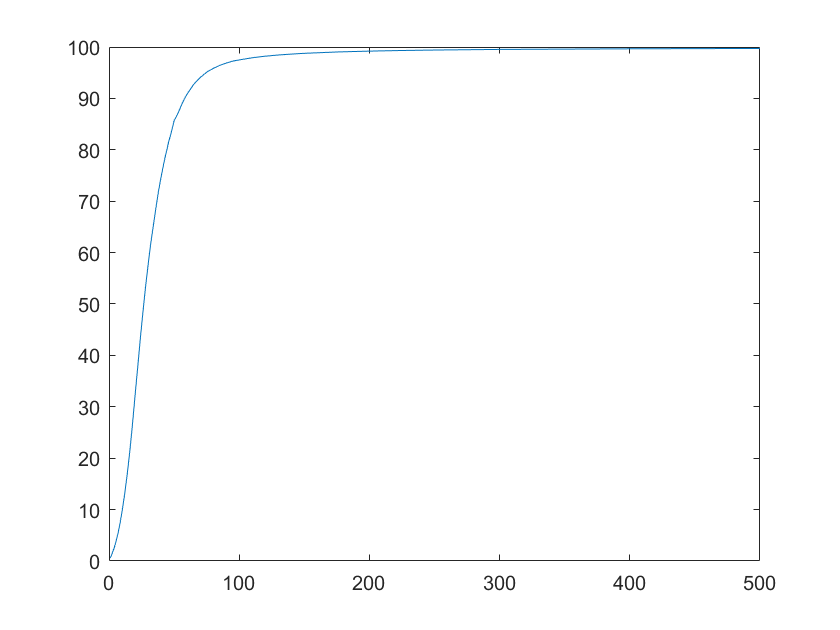

clc;
clf;
clear;
t = [1 2 4 6 8 10 12 14 16 18 20 22 24 26 28 30 32 34 36 38 40 42 44 46 48 50 52 54 56 58 60 65 70 75 ...
    80 85 90 95 100 110 120 130 140 150 175 200 225 250 300 400 500];


y = [0.6 1.19 2.56 4.37 6.68 9.58 12.96 16.89 21.40 26.50 32.12 37.60 43.14 48.27 53.16 57.54 61.69 ...
    65.16 68.63 71.94 74.69 77.29 79.55 81.71 83.52 85.68 86.59 87.70 88.93 89.95 90.85 92.73 94.06 95.10 ...
    95.84 96.42 96.88 97.25 97.49 97.91 98.21 98.44 98.62 98.77 99.03 99.20 99.32 99.41 99.53 99.65 99.72];


plot(t, y);

## 1. Matlab built-in Levenberg-Marquardt method

fun = @(c) c(5) * power(c(1), power(c(2), power(1 - c(3).^t, c(4)))) - y;
options = optimoptions('lsqnonlin','Display','iter');

options.Algorithm = 'levenberg-marquardt';
c0 = [1e-2, 1e-4, 1, 1, 1e2];
[c,resnorm,residual,exitflag,output] = lsqnonlin(fun,c0, [], [], options);


                                        First-Order                    Norm of 
 Iteration  Func-count    Residual       optimality      Lambda           step
     0           6          294709        1.66e+07         0.01
     1          12         37835.2        1.27e+07        0.001       0.513939
     2          18         9862.37        5.46e+05       0.0001        2.09333
     3          29         8408.57        9.95e+06           10        2.58504
     4          37         221.882        2.46e+05         1000      0.0644441
     5          47         123.635        1.08e+04        1e+07     0.00144053
     6          53         93.9054        2.35e+04        1e+06     0.00117673
     7          60         73.2319        1.68e+04        1e+07    0.000969563
     8          66         58.8455        1.03e+04        1e+06    0.000806324
     9          72         46.7125        8.47e+04       100000     0.00288419
    10          78         23.1349        3.97e+04        10000  

format long;
c

c =    0.010125451360499   0.000501289078497   0.985656485865569   1.221307318712747  99.582949034321487


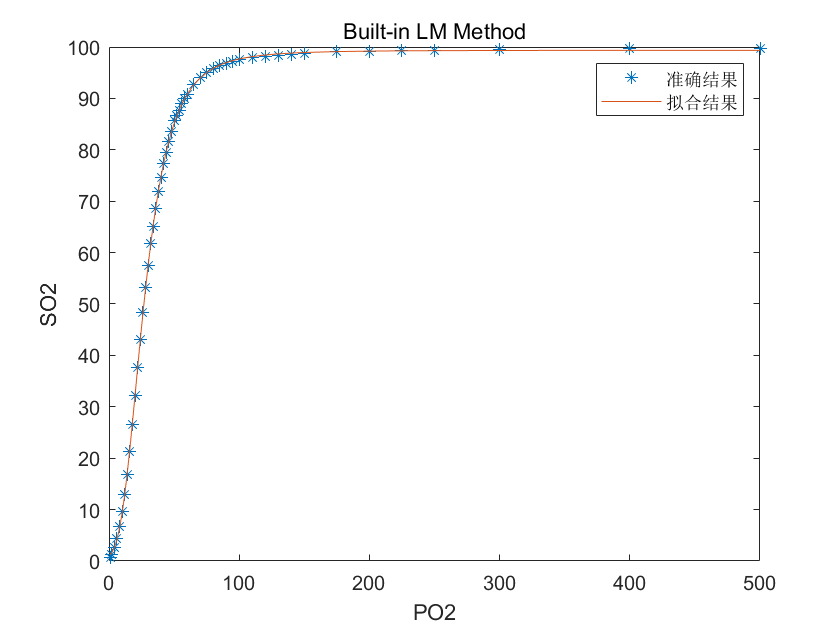

test = c(5) * power(c(1), power(c(2), power(1 - c(3).^t, c(4))));
clf;
plot(t, y, '*');
hold on;
plot(t, test);
xlabel('PO2');
ylabel('SO2');
title('Built-in LM Method');
legend('准确结果', '拟合结果');

## 2. Matlab built-in Trust Region Reflective method

options.Algorithm = 'trust-region-reflective';
c = lsqnonlin(fun,c0, [0, 0, 0.5, 1, 90], [1e-1, 1e-3, 1, 2, 1e2], options);


                                         Norm of      First-order 
 Iteration  Func-count     f(x)          step          optimality
     0          6          294709                       8.3e+06
     1         12         7768.57       0.126261       2.85e+04      
     2         18         531.863       0.192118       1.57e+03      
     3         24         531.863       0.147633       1.57e+03      
     4         30          446.25      0.0369083       1.11e+03      
     5         36         268.242      0.0738165       1.19e+03      
     6         42         156.003       0.147633            889      
     7         48         77.9899       0.295266            733      
     8         54         26.4285       0.104156            372      
     9         60         19.2098      0.0673764       1.07e+03      
    10         66         9.53902      0.0168441            135      
    11         72         7.13725      0.0336882             93      
    12         78         4.8655

c

c =         0.0101258211351008      0.000501361892185253         0.985656060961151          1.22132067123979          99.5829927970717


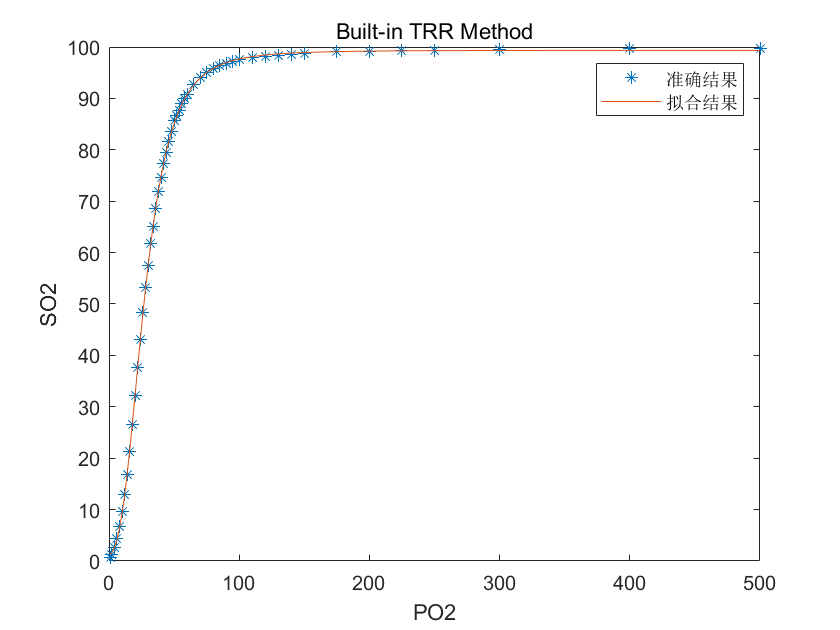

test = c(5) * power(c(1), power(c(2), power(1 - c(3).^t, c(4))));
clf;
plot(t, y, '*');
hold on;
plot(t, test);
xlabel('PO2');
ylabel('SO2');
title('Built-in TRR Method');
legend('准确结果', '拟合结果');

## 3. 参考文献中的结果

 [1] Du Toit R. The choice of an appropriate nonlinear model for the relationship between certain variables in respiratory physiology[J]. South African Statistical Journal, 1984, 18(2): 161-176.

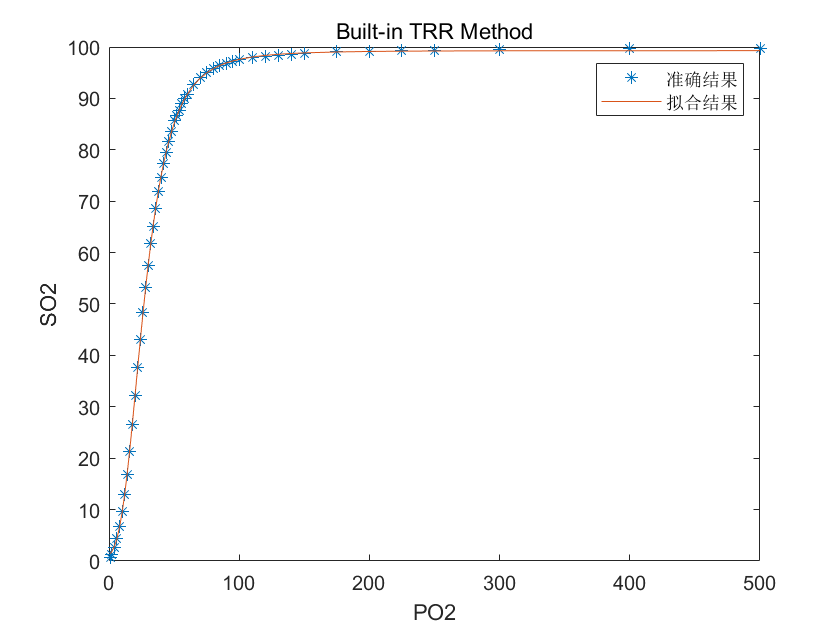

clf;
c(1) = 0.0124904951;
c(2) = 0.000740817624;
c(3) = 0.984303206;
c(4) = 1.280779869;
c(5) = 99.607959;
test = c(5) * power(c(1), power(c(2), power(1 - c(3).^t, c(4))));
clf;
plot(t, y, '*');
hold on;
plot(t, test);
xlabel('PO2');
ylabel('SO2');
title('Built-in TRR Method');
legend('准确结果', '拟合结果');

0.5*norm(test - y)^2

ans =    1.566120659318736


## 4. 自己实现的Levenberg-Marquardt算法

% syms x1 x2 x3 x4 x5 P;
% c1 = 1/(1+exp(x1));
% c2 = 1/(1+exp(x2));
% c3 = 1/(1+exp(x3));
% c4 = 1 + exp(x4);
% c5 = x5;
syms c1 c2 c3 c4 c5 P;
f = c5 * power(c1, power(c2, power(1 - power(c3, P), c4)));
P = t';
f = eval(f);
% J = jacobian(F,[x1, x2, x3, x4, x5]);
J = jacobian(f,[c1, c2, c3, c4, c5]);

k = 0;
max_iter = 1e2;
tol = 1e-12;
resnorm = [0];
c = [1e-2, 1e-4, 0.9, 1.2, 1e2]';
% c = [0.01, 0.0007, 0.9, 1.2, 1e2]';
J_temp = double(subs(J, {c1, c2, c3, c4, c5}, {c(1), c(2), c(3), c(4), c(5)}));
r_temp =  double(subs(f, {c1, c2, c3, c4, c5}, {c(1), c(2), c(3), c(4), c(5)})) - y';

H = J_temp' * J_temp;
g = J_temp' * r_temp;


flag = 0;
lam = max(diag(H));

while k < max_iter && flag == 0
    k = k + 1;
    % p = -1 * (H + lam * eye(5)) \ g;
    p = -1 * (H + lam * diag(diag(H))) \ g;
    
    if norm(p) < tol *(norm(c) + tol)
        flag = 1;
    else
        new_c = c + p;
        new_r = double(subs(f, {c1, c2, c3, c4, c5}, {new_c(1), new_c(2), new_c(3), new_c(4), new_c(5)})) - y';
        rho = -1 * (norm(r_temp) - norm(new_r)) / (p' * (J_temp') * r_temp + 0.5 * p' * (J_temp') * J_temp * p);
    end
     if rho > 0
         c = new_c;
         J_temp = double(subs(J, {c1, c2, c3, c4, c5}, {c(1), c(2), c(3), c(4), c(5)}));
         r_temp =  double(subs(f, {c1, c2, c3, c4, c5}, {c(1), c(2), c(3), c(4), c(5)})) - y';
         
         resnorm(end+1) = 0.5 * (norm(r_temp))^2;
         H = J_temp' * J_temp;
         g = J_temp' * r_temp;
         if norm(g, "inf") < tol
             flag = 1;
         end
         lam = lam / 10;
     else
         lam = lam * 10;
     end
end
k

k =     83


flag

flag =      1


c

c =         0.0101255221321554
      0.000501303085063666
         0.985656404541561
          1.22130986863208
          99.5829575191029


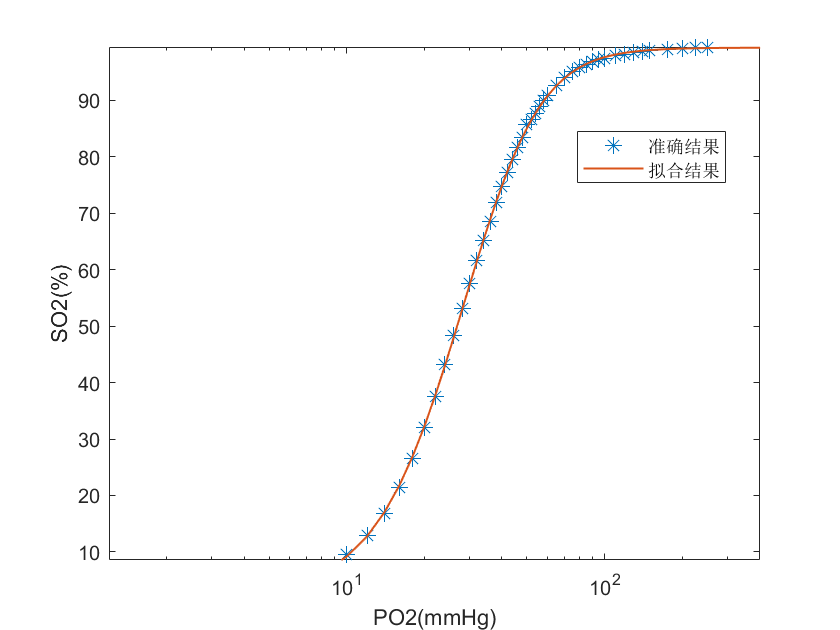

test = c(5) * power(c(1), power(c(2), power(1 - c(3).^t, c(4))));

clf;
semilogx(t, y, '*', 'MarkerSize', 8);
%plot(t, y, '*', 'MarkerSize', 8);
hold on;
semilogx(t, test, 'LineWidth', 1);
%plot(t, test, 'LineWidth', 1);
xlabel('PO2(mmHg)');
ylabel('SO2(%)');
axis([0,600,0,100])
%title('My LM Method');
legend('准确结果', '拟合结果', 'Location',"best");

% residual norm
0.5*norm(test - y)^2

ans =           1.36205370608579


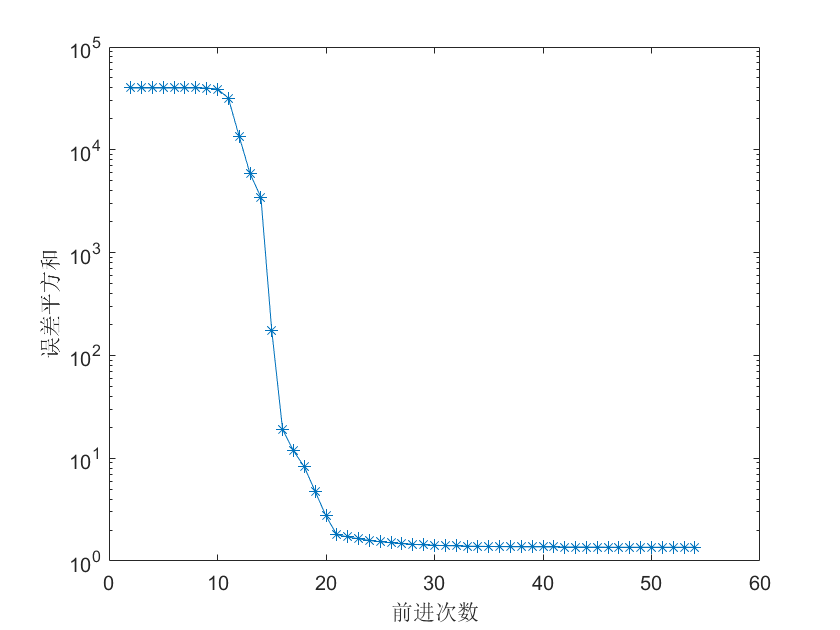

clf;
[~, steps] = size(resnorm);
semilogy(2:steps, resnorm(2:end), '-*');
xlabel('前进次数');
ylabel('误差平方和');